clear;close


% Param
node_num = 9;

T = 100;
mRun = 1 % 重复次数

mRun = 1

m_node = 9; % 监视节点

noiseType = 'guss';

% guss观测噪声方差
beta = 1;
% 混合噪声
impulse = [1 10 0.1] % 小方差 大方差 大的概率

impulse =     1.0000   10.0000    0.1000


% a-stable噪声
alpha = 1.2;
gamma = 1;
msnr = 0;


% attacks
attackType = 'FDI';% FDI Dos

% FDI
FDI_nodes = [3 6 8]

FDI_nodes =      3     6     8


FDIA = [2,100]% 1:标准差，2:均值

FDIA =      2   100


% DoS

% DBSCAN参数
epsilon = 1;
minpts = 2;
% MCKF参数
sigma = 2;% 带宽
kesai = 1e-6;% 精度

% system matrix
global p;
global q;
p = 4; % X
q = 2; % Y

A = [1 0 1 0; ...
    0 1 0 1; ...
    0 0 1 0; ...
    0 0 0 1];

H = [1 0 0 0; ...
    0 1 0 0];

% 系统噪声
sigmaNoise = 0.1;

wt = randn(p,T)*sigmaNoise;
Q = wt*wt'/T;

% real states
x(:,1) = [10 10 1 0]';
for i = 2:T
    x(:,i) = A*x(:,i-1) + wt(:,i);
end

% topology
tp = zeros(node_num);
tp_int = [0 1 0 1 1 0 0 0 0;
    1 0 1 1 1 1 0 0 0;
    0 1 0 0 1 1 0 0 0;
    1 1 0 0 1 0 1 1 0;
    1 1 1 1 0 1 1 1 1;
    0 1 1 0 1 0 0 1 1;
    0 0 0 1 1 0 0 1 0;
    0 0 0 1 1 1 1 0 1;
    0 0 0 0 1 1 0 1 0];

tp_int =tp_int+eye(9);

% tp_int = ones(9)-eye(9);

% % tp_int = ones(9);


xy =[1,1,1,2,2,2,3,3,3;
    1,2,3,1,2,3,1,2,3]';

% tp_int = ones(node_num)
tp_DoS = [0 1 0 1 0 0 0 0 0;
    1 0 1 0 1 0 0 0 0;
    0 1 0 0 0 1 0 0 0;
    1 0 0 0 1 0 1 0 0;
    0 1 0 1 0 1 0 1 0;
    0 0 1 0 1 0 0 0 1;
    0 0 0 1 0 0 0 1 0;
    0 0 0 0 1 0 1 0 1;
    0 0 0 0 0 1 0 1 0];
tp_DoS = tp_DoS+eye(9);
G1 = graph(tp_int)

G1 =   graph - 属性:

    Edges: [29×2 table]
    Nodes: [9×0 table]


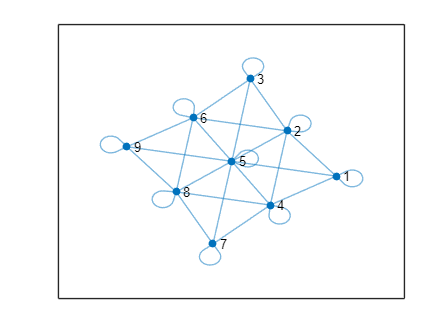

plot(G1)

% tp_DoS = DoSshutdown(tp_int-eye(9),[2,7,9]);


figure(1)

figure(2)
G2 = graph(tp_DoS)

G2 =   graph - 属性:

    Edges: [21×2 table]
    Nodes: [9×0 table]


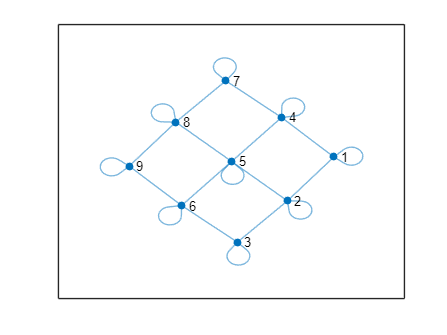

plot(G2)

% gplot(tp_DoS,xy,'-o')


% anaylse
% 单次统计
node_RMSE= struct('attack',[], ...
    'DKF',zeros(1,T),'meanDKF',0, ...
    'DMCKF',zeros(1,T),'meanDMCKF',0, ...
    'TAKF',zeros(1,T),'meanTAKF',0, ...
    'TKF',zeros(1,T),'meanTKF',0, ...
    'TKF_s',zeros(1,T),'meanTKF_s',0);

% 多次统计
RMSE(1:node_num)= struct('attack',[], ...
    'DKF',zeros(1,T),'meanDKF',0, ...
    'DMCKF',zeros(1,T),'meanDMCKF',0, ...
    'TAKF',zeros(1,T),'meanTAKF',0, ...
    'TKF',zeros(1,T),'meanTKF',0, ...
    'TKF_s',zeros(1,T),'meanTKF_s',0);

RMSE_DKF = zeros(node_num,T);
RMSE_DMCKF = zeros(node_num,T);
RMSE_TAKF = zeros(node_num,T);
RMSE_TKF = zeros(node_num,T);
RMSE_TKF_s = zeros(node_num,T);

for k =1:mRun




    for i = 1:node_num
        node(i) = struct( ...
            'y',zeros(q,T),'obser',H,'R',0,'R_trust',0,...% H = round(rand(2,4))
            'topo',0,...
            'attack',0,'mark',0,...% attack type
            'DKF',zeros(p,T),'DMCKF',zeros(p,T), ...
            'TrustScore',zeros(node_num,T),'TrustID',0,...
            'LocKF',zeros(p,T),'TAKF',zeros(p,T), ...
            'Km_idx',[],...
            'TKF_1',zeros(p,T),'TKF_2',zeros(p,T),...
            'Km_Secure_idx',[],...
            'TKF_s1',zeros(p,T),'TKF_s2',zeros(p,T),...
            'P_DKF',eye(p),'P_DMCKF',eye(p),'P_TAKF',eye(p), ...
            'P_TKF_1',eye(p),'P_TKF_2',eye(p), ...
            'P_TKF_s1',eye(p),'P_TKF_s2',eye(p));


        node(i).DKF(:,1) = x(:,1); 
        node(i).DMCKF(:,1) = x(:,1);
        node(i).TAKF(:,1) = x(:,1);
        node(i).TKF_1(:,1) = x(:,1);
        node(i).TKF_2(:,1) = x(:,1);
        node(i).TKF_s1(:,1) = x(:,1);
        node(i).TKF_s2(:,1) = x(:,1);

        switch noiseType
            case 'guss'
                vt = randn(q,T)*beta^2;
                node(i).R = vt*vt'/T;
                node(i).R_trust = vt*vt'/T;
                node(i).mark = 'guss';

            case 'imp'
                [node(i).R_trust,node(i).R,vt] = impulse_noise(q,T,impulse(1),impulse(2),impulse(3));
                node(i).mark = 'imp';

            case 'levy'
                vt(1,:) = alpha_dist(zeros(1,T),alpha,0,gamma,0,msnr);
                vt(2,:) = alpha_dist(zeros(1,T),alpha,0,gamma,0,msnr);
                node(i).R = vt*vt'/T;
                node(i).R_trust = vt*vt'/T;
                node(i).mark = 'Levy';

            otherwise
                vt = randn(q,T)*beta^2;node(i).R = vt*vt'/T;
                node(i).R_trust = node(i).R;
        end

        for t = 1:T
            node(i).y(:,t) = node(i).obser*x(:,t) + vt(:,t);
        end

        tp = tp_int;
        switch attackType
            case 'FDI'
                FDIA_c = randn(q,T)*FDIA(1)+FDIA(2);
                if any(i ==FDI_nodes)
                    node(i).y = node(i).y + FDIA_c;
                    %          node(i).y = node(i).y + node(i).obser*FDIA_c;
                    node(i).attack = "FDI";
                    node_RMSE(i).attack = "FDI";
                    RMSE(i).attack = "FDI";
                end
                node(i).topo = tp_int(i,:);

            case 'Dos'
                tp = tp_DoS;
                node(i).attack = "DoS";
                node(i).topo = tp(i,:);
                node_RMSE(i).attack = "DoS";
                RMSE(i).attack = "DoS";
            otherwise
                node(i).attack = "none";
                node(i).topo = tp_int(i,:);
                node_RMSE(i).attack = 'none';
                RMSE(i).attack = "none";
        end

    end



DKF（真·分布式KF）

    t1 = tic;
    for t = 1:T-1
        for i = 1:node_num
            %         y_c = node(i).y(:,t+1)';
            %         H_c = node(i).obser;
            %         R_c = node(i).R;
            y_c = [];
            H_c = [];
            R_c =[];
            Toplist = node(i).topo;
            for ii = 1:node_num
                if Toplist(ii) == 1
                    y_c = [y_c,node(ii).y(:,t+1)'];
                    H_c = [H_c;node(ii).obser];
                    R_c = blkdiag(R_c,node(ii).R);
                end

            end
            y_c = y_c';
            [node(i).P_DKF,node(i).DKF(:,t+1)] = KF(A,node(i).P_DKF,H_c,R_c,Q,node(i).DKF(:,t),y_c);
        end

    end
    time_DKF = toc(t1);

DMCKF（分布式MCKF）

    t1 = tic;
    for t = 1:T-1
        for i = 1:node_num
            y_c = node(i).y(:,t+1)';
            H_c = node(i).obser;
            R_c = node(i).R;
            Toplist = node(i).topo;
            for ii = 1:node_num
                if Toplist(ii) == 1;
                    y_c = [y_c,node(ii).y(:,t+1)'];
                    H_c = [H_c;node(ii).obser];
                    R_c = blkdiag(R_c,node(ii).R);
                end
            end
            y_c = y_c';
            [node(i).P_DMCKF,node(i).DMCKF(:,t+1)] = MCKF(A,node(i).P_DMCKF,H_c,R_c,Q,node(i).DMCKF(:,t),y_c,sigma,kesai);
        end

    end

    time_DMCKF = toc(t1);



Trust Aware Filter

    t1 = tic;

    List_trustID = cell(T,node_num);

    for t = 1:T-1

        dataTrust = zeros(node_num,1);
        for i = 1:node_num
            [~,node(i).LocKF(:,t+1),~] = KF(A,node(i).P_TAKF,node(i).obser,node(i).R,Q,node(i).TAKF(:,t),node(i).y(:,t+1));
            %         y_c = node(i).y(:,t+1)';
            %         H_c = node(i).obser;
            %         R_c = node(i).R;
            y_c = [];
            H_c = [];
            R_c = [];
            Toplist = node(i).topo;

            for ii = 1:node_num
                if Toplist(ii) == 1;
                    node(i).TrustScore(ii,t) = cal_detect(node(ii).y(:,t+1),node(ii).obser,A*node(i).P_TAKF*A'+ Q,node(i).R,node(i).LocKF(:,t+1));
                end
                dataTrust(ii,:) = node(i).TrustScore(ii,t);
            end


            nz_id = find(dataTrust);
            dataclust = dataTrust( dataTrust~= 0);
            idx = dbscan(dataclust,epsilon,minpts,"Distance","euclidean");
            [IDmean,id] = calculate_means(dataclust',idx);
            [~,kk] = min(IDmean);
            id(kk);
            ID = [nz_id,idx];


            node(i).TrustID = ID(ID(:,2)==id(kk),1);

            List_trustID(t,i) = {node(i).TrustID};

            for ii = 1:node_num
                if Toplist(ii) == 1;
                    if any(ii ==node(i).TrustID)
                        % if node(i).TrustScore(ii,t) <2
                        y_c = [y_c,node(ii).y(:,t+1)'];
                        H_c = [H_c;node(ii).obser];
                        R_c = blkdiag(R_c,node(ii).R);
                    end
                end
            end
            y_c = y_c';
            [node(i).P_TAKF,node(i).TAKF(:,t+1)] = MCKF(A,node(i).P_TAKF,H_c,R_c,Q,node(i).TAKF(:,t),y_c,sigma,kesai);

        end
    end

    time_Trust_DBCAN_KF = toc(t1);


IF-TrustbasedKF

    for t = 1:T-1
        for i = 1:node_num
            [node(i).P_TKF_1,node(i).TKF_1(:,t+1)] = KF(A,node(i).P_TKF_2,node(i).obser,node(i).R,Q,node(i).TKF_2(:,t),node(i).y(:,t));
        end

        for i = 1:node_num
            Toplist = node(i).topo;

            dataKm = [];

            for ii = 1:node_num
                if Toplist(ii) == 1
                    dataKm =[dataKm,node(ii).TKF_1(:,t+1)];
                end
            end
            [idxKm] = kmeans(dataKm',2);

            [means,unique_labels] = calculate_means(dataKm, idxKm);
            meamloss = abs(mean(means - node(i).TKF_2(:,t)));

            if meamloss(1)<meamloss(2)
                ID = unique_labels(1);
            else
                ID = unique_labels(2);
            end
            idtemp = (idxKm == ID);
            node(i).TKF_2(:,t+1) = mean(dataKm(:,idtemp),2);

            PP = zeros(4);
            k = 1;
            kk = 0;


            for ii = 1:node_num
                if Toplist(ii) == 1
                    node(ii).Km_idx = idxKm(k);
                    k = k+1;
                end
                if node(ii).Km_idx == ID
                    if Toplist(ii) == 1
                        PP = PP + node(ii).P_TKF_1;
                        kk = kk+1;
                    end
                end

            end
            node(i).P_TKF_2 = PP/kk;

        end
    end



DSP-Trustbased-KF-secured fussion

若包含安全节点——使用major voting


    for t = 1:T-1
        for i = 1:node_num
            [node(i).P_TKF_s1,node(i).TKF_s1(:,t+1)] = KF(A,node(i).P_TKF_s2,node(i).obser,node(i).R,Q,node(i).TKF_s2(:,t),node(i).y(:,t));
        end

        for i = 1:node_num
            Toplist = node(i).topo;

            dataKm = [];

            for ii = 1:node_num
                if Toplist(ii) == 1
                    dataKm =[dataKm,node(ii).TKF_s1(:,t+1)];
                end
            end
            [idxKm] = kmeans(dataKm',2);

            node_ID =[find(Toplist)',idxKm];

            if Toplist(5) == 1
                ID = node_ID(find(node_ID(:,1)==5),2);
                idtemp = (idxKm == ID);
                node(i).TKF_s2(:,t+1) = mean(dataKm(:,idtemp),2);

            else
                ID = mode(idxKm);
                idtemp = (idxKm == ID);
                node(i).TKF_s2(:,t+1) = mean(dataKm(:,idtemp),2);

            end


            PP = zeros(4);
            k = 1;
            kk = 0;
            for ii = 1:node_num
                if Toplist(ii) == 1
                    node(ii).Km_Secure_idx = idxKm(k);
                    k = k+1;
                end
                if node(ii).Km_Secure_idx == ID
                    if Toplist(ii) == 1
                        PP = PP + node(ii).P_TKF_s1;
                        kk = kk+1;
                    end
                end

            end
            node(i).P_TKF_s2 = PP/kk;

        end
    end



    % 性能评估
    for i =1:node_num
        for t = 1:T-1
            node_RMSE(i).DKF(t+1) = norm(node(i).DKF(:,t+1)-x(:,t+1));
            node_RMSE(i).DMCKF(t+1) = norm(node(i).DMCKF(:,t+1)-x(:,t+1));
            node_RMSE(i).TAKF(t+1) = norm(node(i).TAKF(:,t+1)-x(:,t+1));
            node_RMSE(i).TKF(t+1) = norm(node(i).TKF_2(:,t+1)-x(:,t+1));
            node_RMSE(i).TKF_s(t+1) = norm(node(i).TKF_s2(:,t+1)-x(:,t+1));
        end
        node_RMSE(i).meanDKF = mean(node_RMSE(i).DKF);
        node_RMSE(i).meanDMCKF = mean(node_RMSE(i).DMCKF);
        node_RMSE(i).meanTAKF = mean(node_RMSE(i).TAKF);
        node_RMSE(i).meanTKF = mean(node_RMSE(i).TKF);
        node_RMSE(i).meanTKF_s = mean(node_RMSE(i).TKF_s);
    end

    for i =1:node_num
        RMSE(i).DKF =  RMSE(i).DKF + node_RMSE(i).DKF/mRun;
        RMSE(i).DMCKF = RMSE(i).DMCKF + node_RMSE(i).DMCKF/mRun;
        RMSE(i).TAKF = RMSE(i).TAKF + node_RMSE(i).TAKF/mRun;
        RMSE(i).TKF = RMSE(i).TKF + node_RMSE(i).TKF/mRun;
        RMSE(i).TKF_s = RMSE(i).TKF_s + node_RMSE(i).TKF_s/mRun;
    end

end
    for i =1:node_num
        RMSE(i).meanDKF = mean(RMSE(i).DKF);
        RMSE(i).meanDMCKF = mean(RMSE(i).DMCKF);
        RMSE(i).meanTAKF = mean(RMSE(i).TAKF);
        RMSE(i).meanTKF = mean(RMSE(i).TKF);
        RMSE(i).meanTKF_s = mean(RMSE(i).TKF_s);
    end
    

% save("RMSE_int_Guss.mat","RMSE")
% save("RMSE_DoS_Guss.mat","RMSE")
% save("RMSE_DoS_imp02","RMSE")
% save("RMSE_DoS_levy12","RMSE")
% save("RMSE_int_levy12","RMSE")
% save("RMSE_DoS_imp","RMSE")
% save("RMSE_int_imp","RMSE")

% figure
figure()

ed = 100

ed = 100

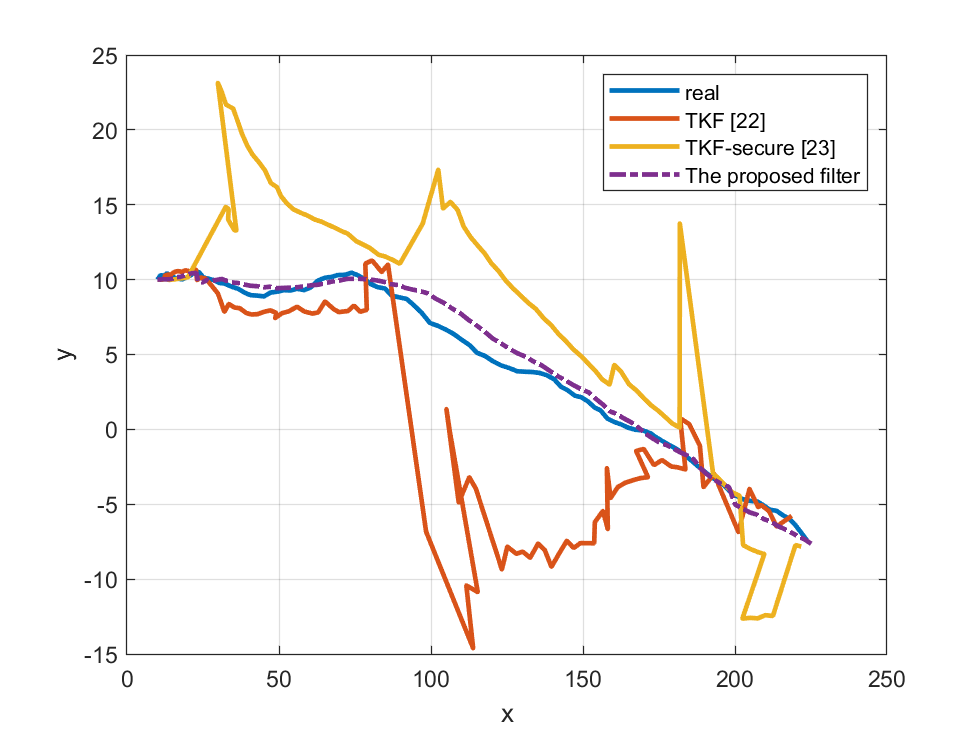

hold on
grid on
box on
plot(x(1,1:ed),x(2,1:ed),'-',LineWidth=2)
plot(node(5).TKF_2(1,1:ed),node(5).TKF_2(2,1:ed),'-',LineWidth=2)
plot(node(5).TKF_s2(1,1:ed),node(5).TKF_s2(2,1:ed),'-',LineWidth=2)
plot(node(5).TAKF(1,1:ed),node(5).TAKF(2,1:ed),'-.',LineWidth=2)
% plot(node(7).TAKF(1,1:ed),node(7).TAKF(2,1:ed),'-.',LineWidth=2)

legend('real',"TKF [22]",'TKF-secure [23]','The proposed filter')
xlabel('x');ylabel('y')
print(gcf,'-depsc2','trac-DoS.eps');

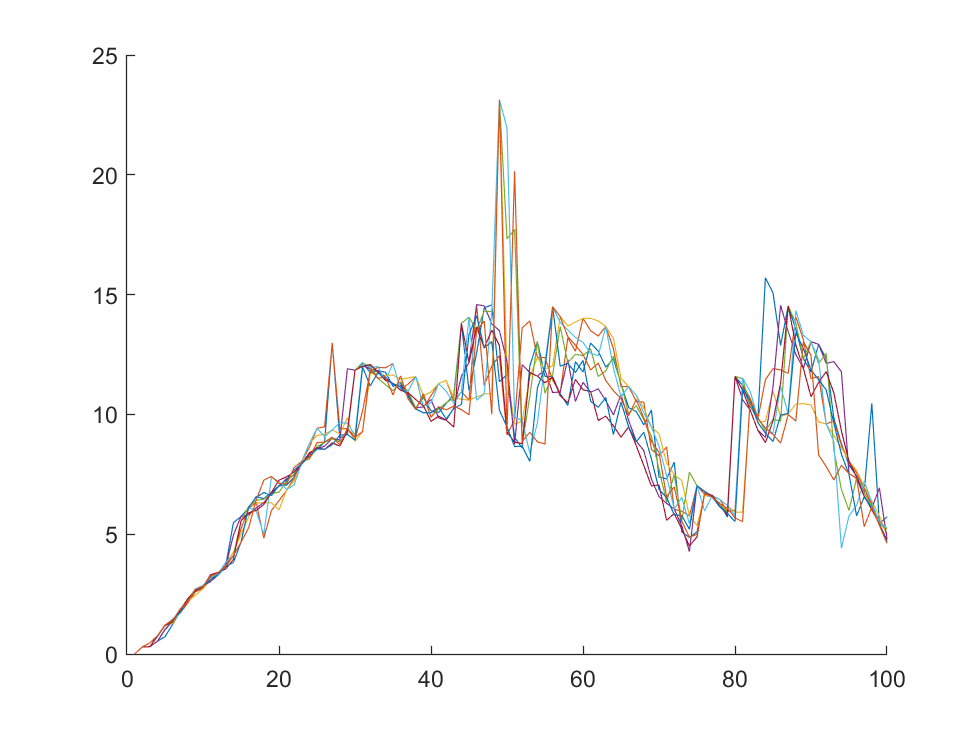

% title('Tracking Result')


figure
hold on
for i = 1:node_num
    plot(node_RMSE(i).TKF)
end

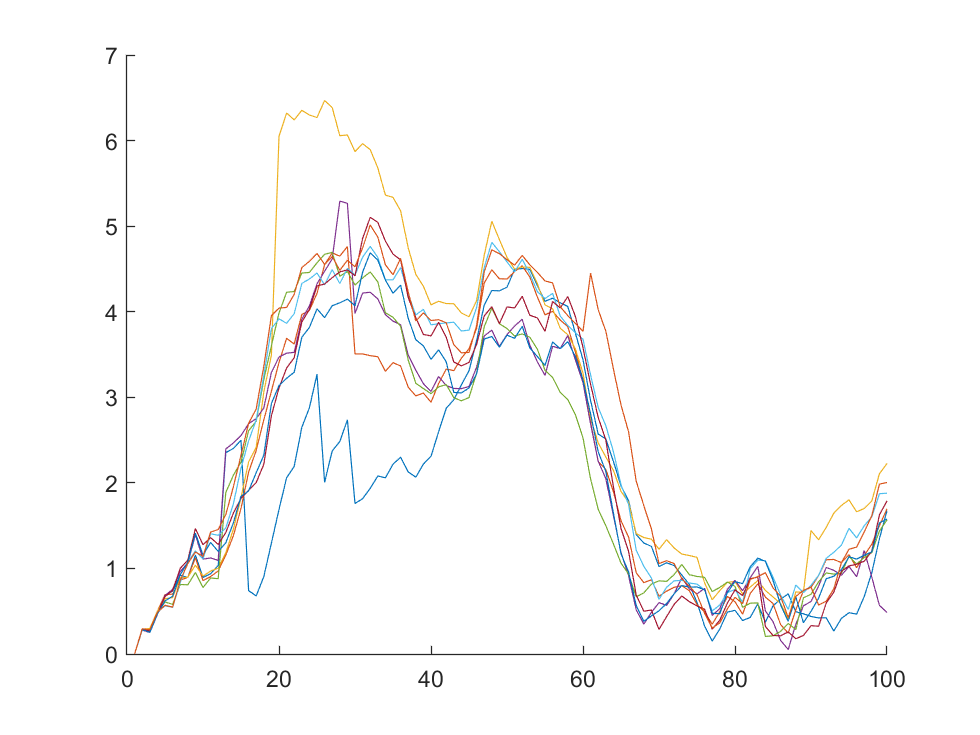

figure
hold on
for i = 1:node_num
    plot(node_RMSE(i).TAKF)
end

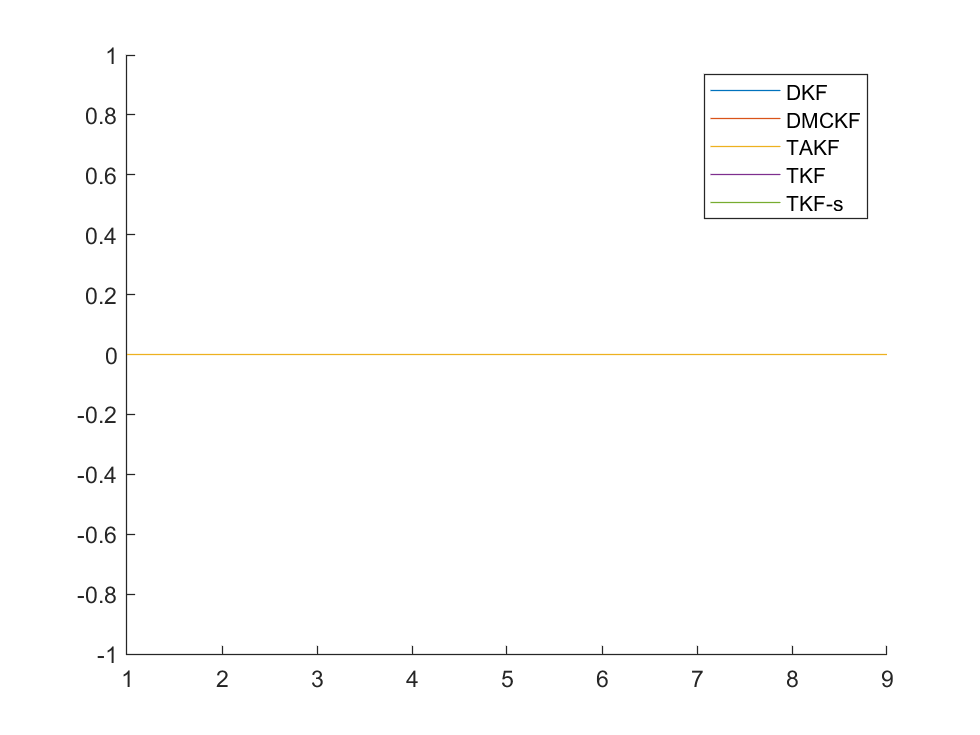

figure
hold on
plot(RMSE_DKF)
plot(RMSE_DMCKF)
plot(RMSE_TAKF)
plot(RMSE_TKF)
plot(RMSE_TKF_s)
legend('DKF','DMCKF','TAKF','TKF','TKF-s')


save('tracking')